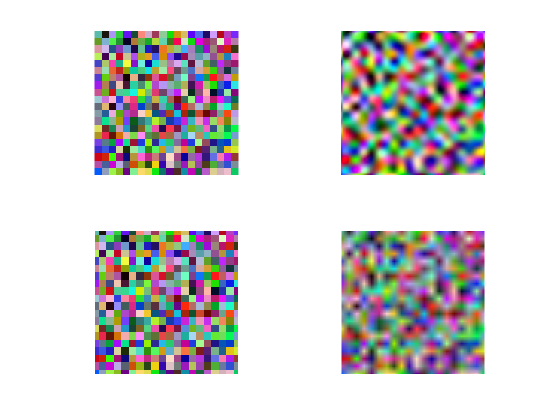

clear variables;
figure(2)
subplot 221

S = rand(20, 20, 3);

imshow(S) % pokaż rysunek

xi=1:0.1:20;
yi=1:0.1:20;
[X, Y]=meshgrid(xi,yi);
S1(:,:,1)=interp2(S(:,:,1),X,Y,'spline');
S1(:,:,2)=interp2(S(:,:,2),X,Y,'spline');
S1(:,:,3)=interp2(S(:,:,3),X,Y,'spline');
subplot 222
imshow(S1)

S2(:,:,1)=interp2(S(:,:,1),X,Y,'nearest');
S2(:,:,2)=interp2(S(:,:,2),X,Y,'nearest');
S2(:,:,3)=interp2(S(:,:,3),X,Y,'nearest');
subplot 223
imshow(S2)

S3(:,:,1)=interp2(S(:,:,1),X,Y,'linear');
S3(:,:,2)=interp2(S(:,:,2),X,Y,'linear');
S3(:,:,3)=interp2(S(:,:,3),X,Y,'linear');
subplot 224
imshow(S3)